# Equations with heterogeneous coefficients

clear
set_demo_defaults
col = marc_colors();

## Discretization of the heterogeneous coefficient

Consider the discretization of incompressible flow with heterogenous hydraulic conductivity

Continuous equation: $-\nabla\cdot\left[K(\mathbf{x})\nabla h] = f_s$ on $x\in\left[0,\,L\right]$

Discrete equation:      `-D*[Kd*G]*h = fs`

Here we have introduced a new (Nx+1) by (Nx+1) matrix `Kd` that accounts for the heterogeneous coefficient on the cell faces.

However, the hydraulic conductivity is generally evaluated at the cell center and must be *averaged* to the cell faces. 

The discrete equation for the flux on the $i$-th face is


$$q_i = -K_{i-1/2}\frac{h_i-h_{i-1}}{\Delta x}$$


where $K_{i-1/2}$ is a suitable average of $K_{i-1}$ and $K_i$. This average could be either:

- Arithmetic: $K_{i-1/2} = \frac{K_{i-1}+K_i}{2}$

- Harmonic: $K_{i-1/2} = \frac{2}{\frac{1}{K_{i-1}}+\frac{1}{K_i}}$

These two formulas a special cases of a general power-law mean


$$\langle K\rangle_p = \left(\frac{1}{2}\left(K_1^p+K_2^p\right)\right)^{1/p}$$


where the arithmetic average is recovered for $p=1$ and the harmonic average for $p=-1$. 

Suppose we compute a Nx+1 by 1 column vector `Kmean` that contains these averages to the faces. then we could compute the flux in Matlab using elementwise multiplication 

`q = -Kmean.*(G*h)`

While this is correct, it does not allow us to write the linerar operator `L = -D*Kd*G`.

An equivalent way to compute the fluxes is to place the vector Kman on the diagonal of the (nx+1) by (Nx+1) matrix Kd and then use matrix vector multiplication

`q = -Kd*(G*h)`

Therefore the matrix `Kd` simply contais the averages of $K$fron the cells to the faces along its diagonal.

## Implementation in `comp_mean.m`

The computation of these averages will be encapsulated in the function `comp_mean.m`. From the function `build_ops.m` we have the `M` matrix which "averages" values from the cell centers to the faces. This is an arithmetic average! Given M we can implement the averages as follows:

- arithmetic (p=1): `Kmean = M*K`

- harmonic (p=-1): `Kmean = 1./(M*(1./K))`

- general power mean: `Kmean = (M*K.^p).^(1/p)`

The resultin column vector `Kmean` is then placed on the diagonal of the Nf by Nf matrix `Kd`.

## Example: Heterogeneous column - Analytic solution

Consider one-dimensional flow through a column of length L = 100 cm

$-\nabla\left[K(x)\nabla h\right] = 0$ on $x\in\left[0,\,L\right]$

 with heterogeneous permeability


$$K(x) = \begin{cases}
 K_1=5\times10^{-3},&\mbox{ for }x<0.2 \mbox{  cm} \\
K_2 =5\times10^{-5},&\mbox{ for }0.2<x<0.4 \mbox{  cm} \\
K_3=5\times10^{-3},&\mbox{ for }x>0.4 \mbox{  cm}
\end{cases}$$


and two Dirichlet boundary conditions, $h_L = 120$ cm and $h_R = 100$ cm.

%% Parameters
K = [5e-3 5e-5 5e-3 ];  % hydraulic conductivity values
l = [20 20 60];         % length of the corresponding coumn segments
hL = 120;               % head on the left
hR = 100;               % head on the right

The head is piecewise linear and the flux is constant. The analytic solution can be obtained computing the heads, $h_1$and $h_2$, at the two interfaces between the three segments. Applying Darcy's law to each segment 


$$q = -K_1\frac{h_1-h_L}{l_1} = -K_2\frac{h_2-h_1}{l_2}=-K_3\frac{h_R-h_2}{l_3}$$


we have three simultaneous equations that can be solved for $h_1$and $h_2$.

$h_1 = \frac{K_1(K_2l_3+l_2K_3)h_L+l_1K_2K_3h_R}{K_1K_2l_3 + K_1l_2K_3 + l_1K_2K_3}$ and $h_2 = \frac{K_3(K_1l_2+l_1K_2)h_R+l_3K_1K_2h_L}{K_1K_2l_3 + K_1l_2K_3 + l_1K_2K_3}$

the flux can then be obtained either by computing the weighted harmonic average of $K_{\perp}^*$ and applying Darcy to the whole column, $q = -K_\perp^*\frac{h_R-h_L}{L}$ or by applying Darcy's law to any segment as shown above.

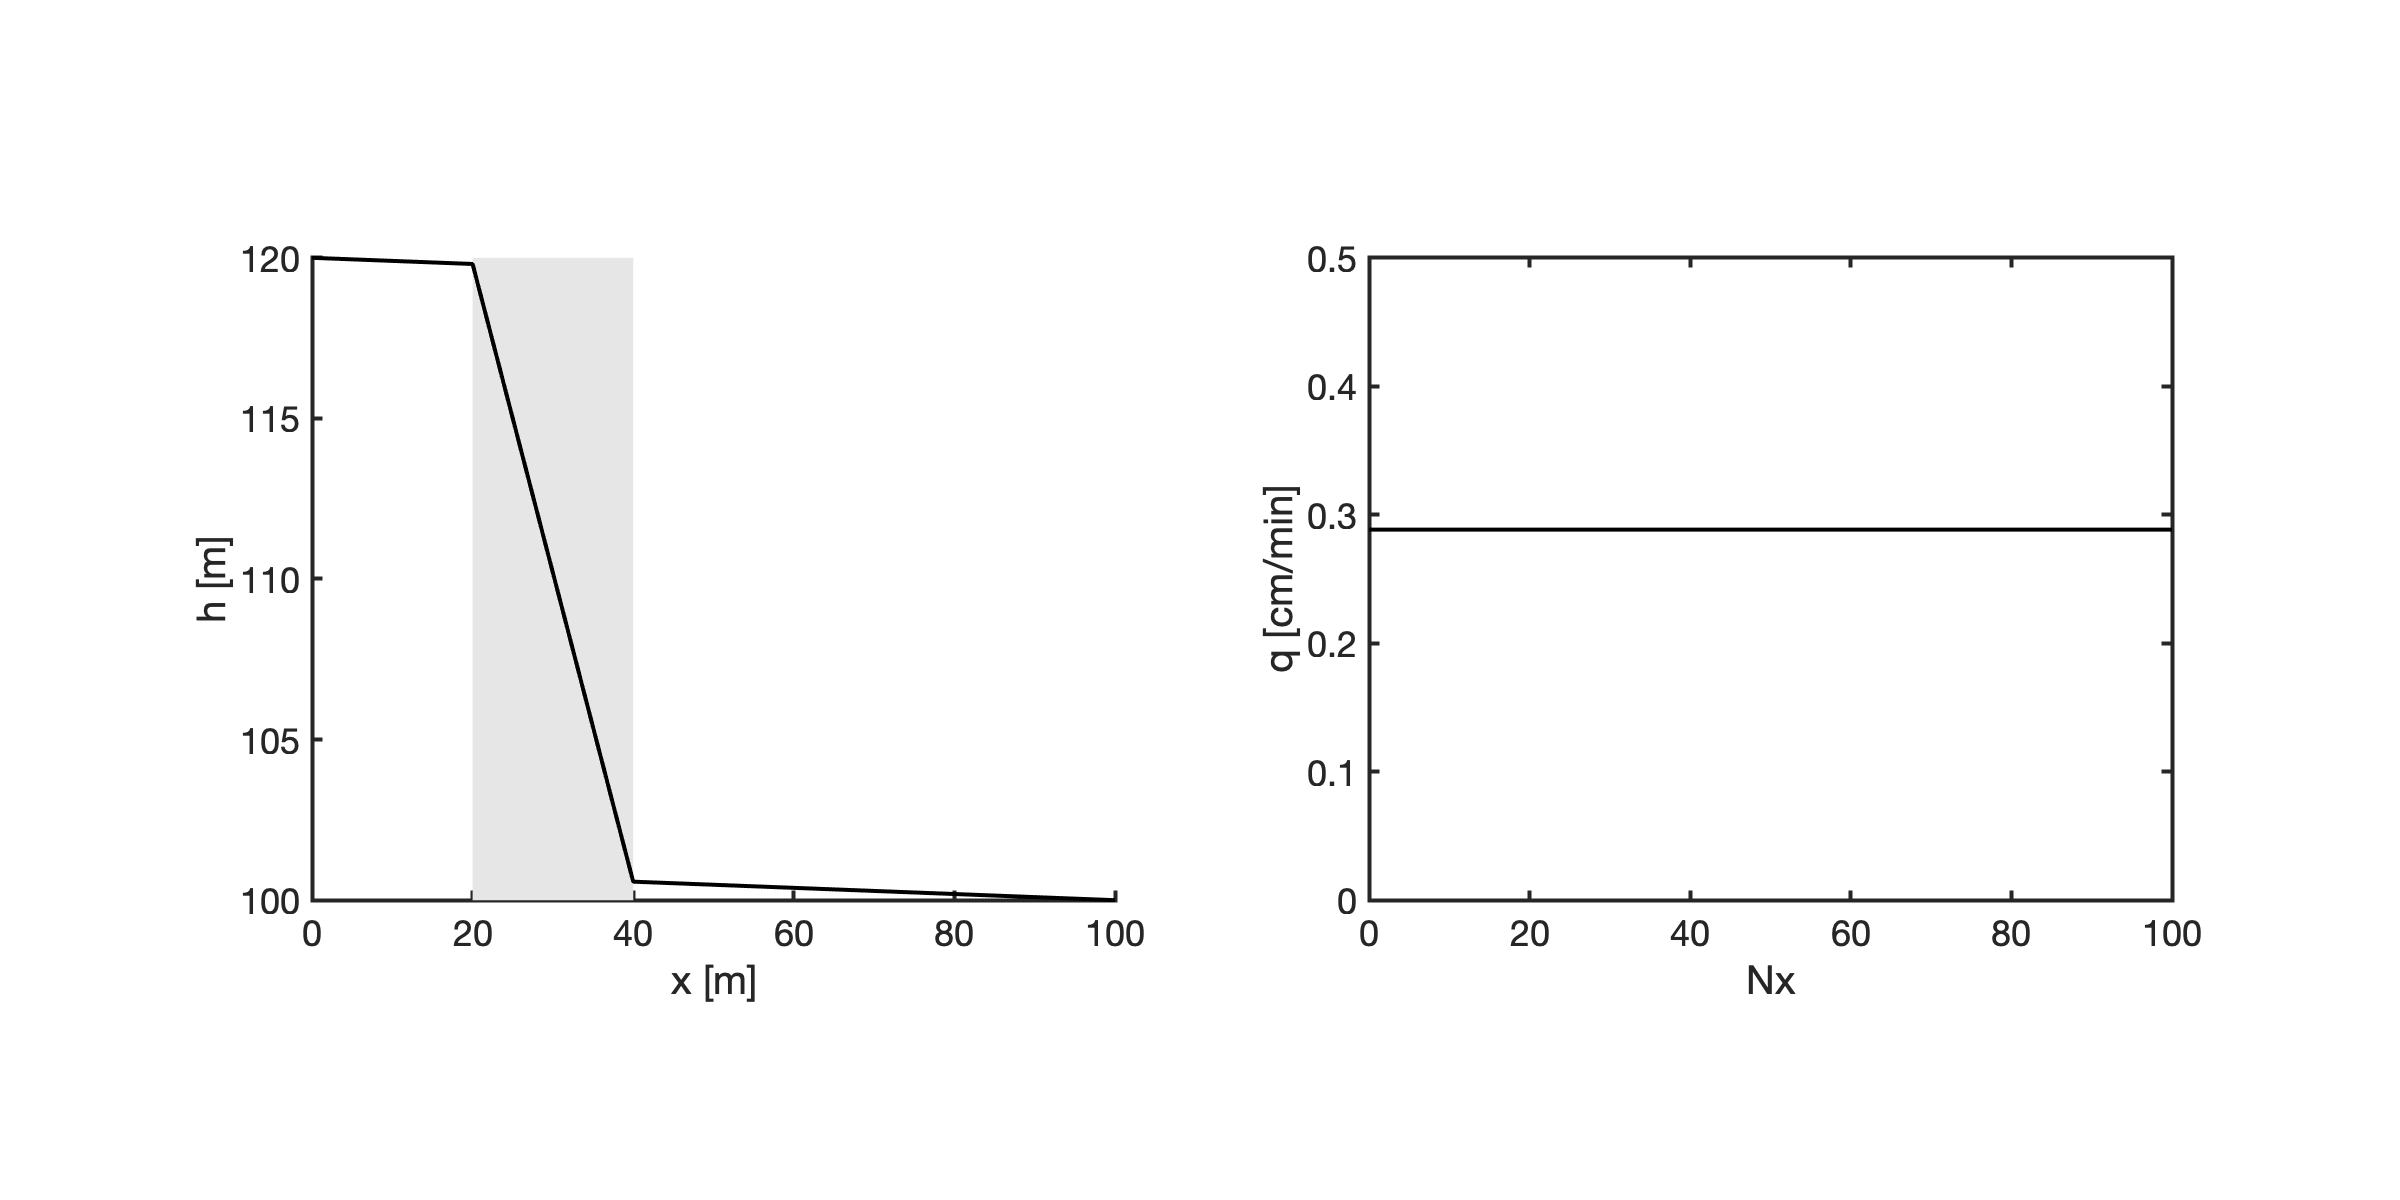

%% Analytic solution
denom = K(1)*K(2)*l(3) + K(1)*l(2)*K(3) + l(1)*K(2)*K(3);
h1 = (K(1)*(K(2)*l(3)+l(2)*K(3))*hL+l(1)*K(2)*K(3)*hR)/denom;
h2 = (K(3)*(K(1)*l(2)+l(1)*K(2))*hR+l(3)*K(1)*K(2)*hL)/denom;
ha = [hL h1 h2 hR];
qa = - K(1)*(h1-hL)/l(1);
xa = [0 cumsum(l)];

figure('position',[10 10 1200 600])
subplot 121
patch([20 40 40 20],[100 100 120 120],.9*[1 1 1],'edgecolor','none'), hold on
plot(xa,ha,'k-','linewidth',2)
xlabel 'x [m]', ylabel 'h [m]'
pbaspect([1 .8 1])

subplot 122
% semilogy([0 Nx(end)],qa*[1 1],'k-','linewidth',2), hold on
plot([0 100],qa*[1 1]*6000,'k-','linewidth',2) % 6000 is conversion from m/s to cm/min!
xlim([0 100]),ylim([0 0.5])
xlabel 'Nx', ylabel 'q [cm/min]'
pbaspect([1 .8 1])

The solution shows that most of the head drop occurs in the second segment (shaded grey) where the hydraulic conductivity is lower. This indicates that most of the energy in the flow is consumed by flowing across the low conductivity segment.

## Heterogeneous column - Numerical solution

We will test the convergence of the numerical solution for both the head and the flux with different means as the grid is refined. We will consider the following grids

Nx = [1 2 3 4 5 6]*5;
Grid.xmin = 0; Grid.xmax = xa(end);
Kvec = K;
% create custom color map
N = length(Nx);
RED = repmat(col.red,N,1);
BLUE = repmat(col.blue,N,1);
ALPHA = repmat(linspace(0,1,N)',1,3);
COL = BLUE.*ALPHA + RED.*(1-ALPHA);

### Arithmetic Mean

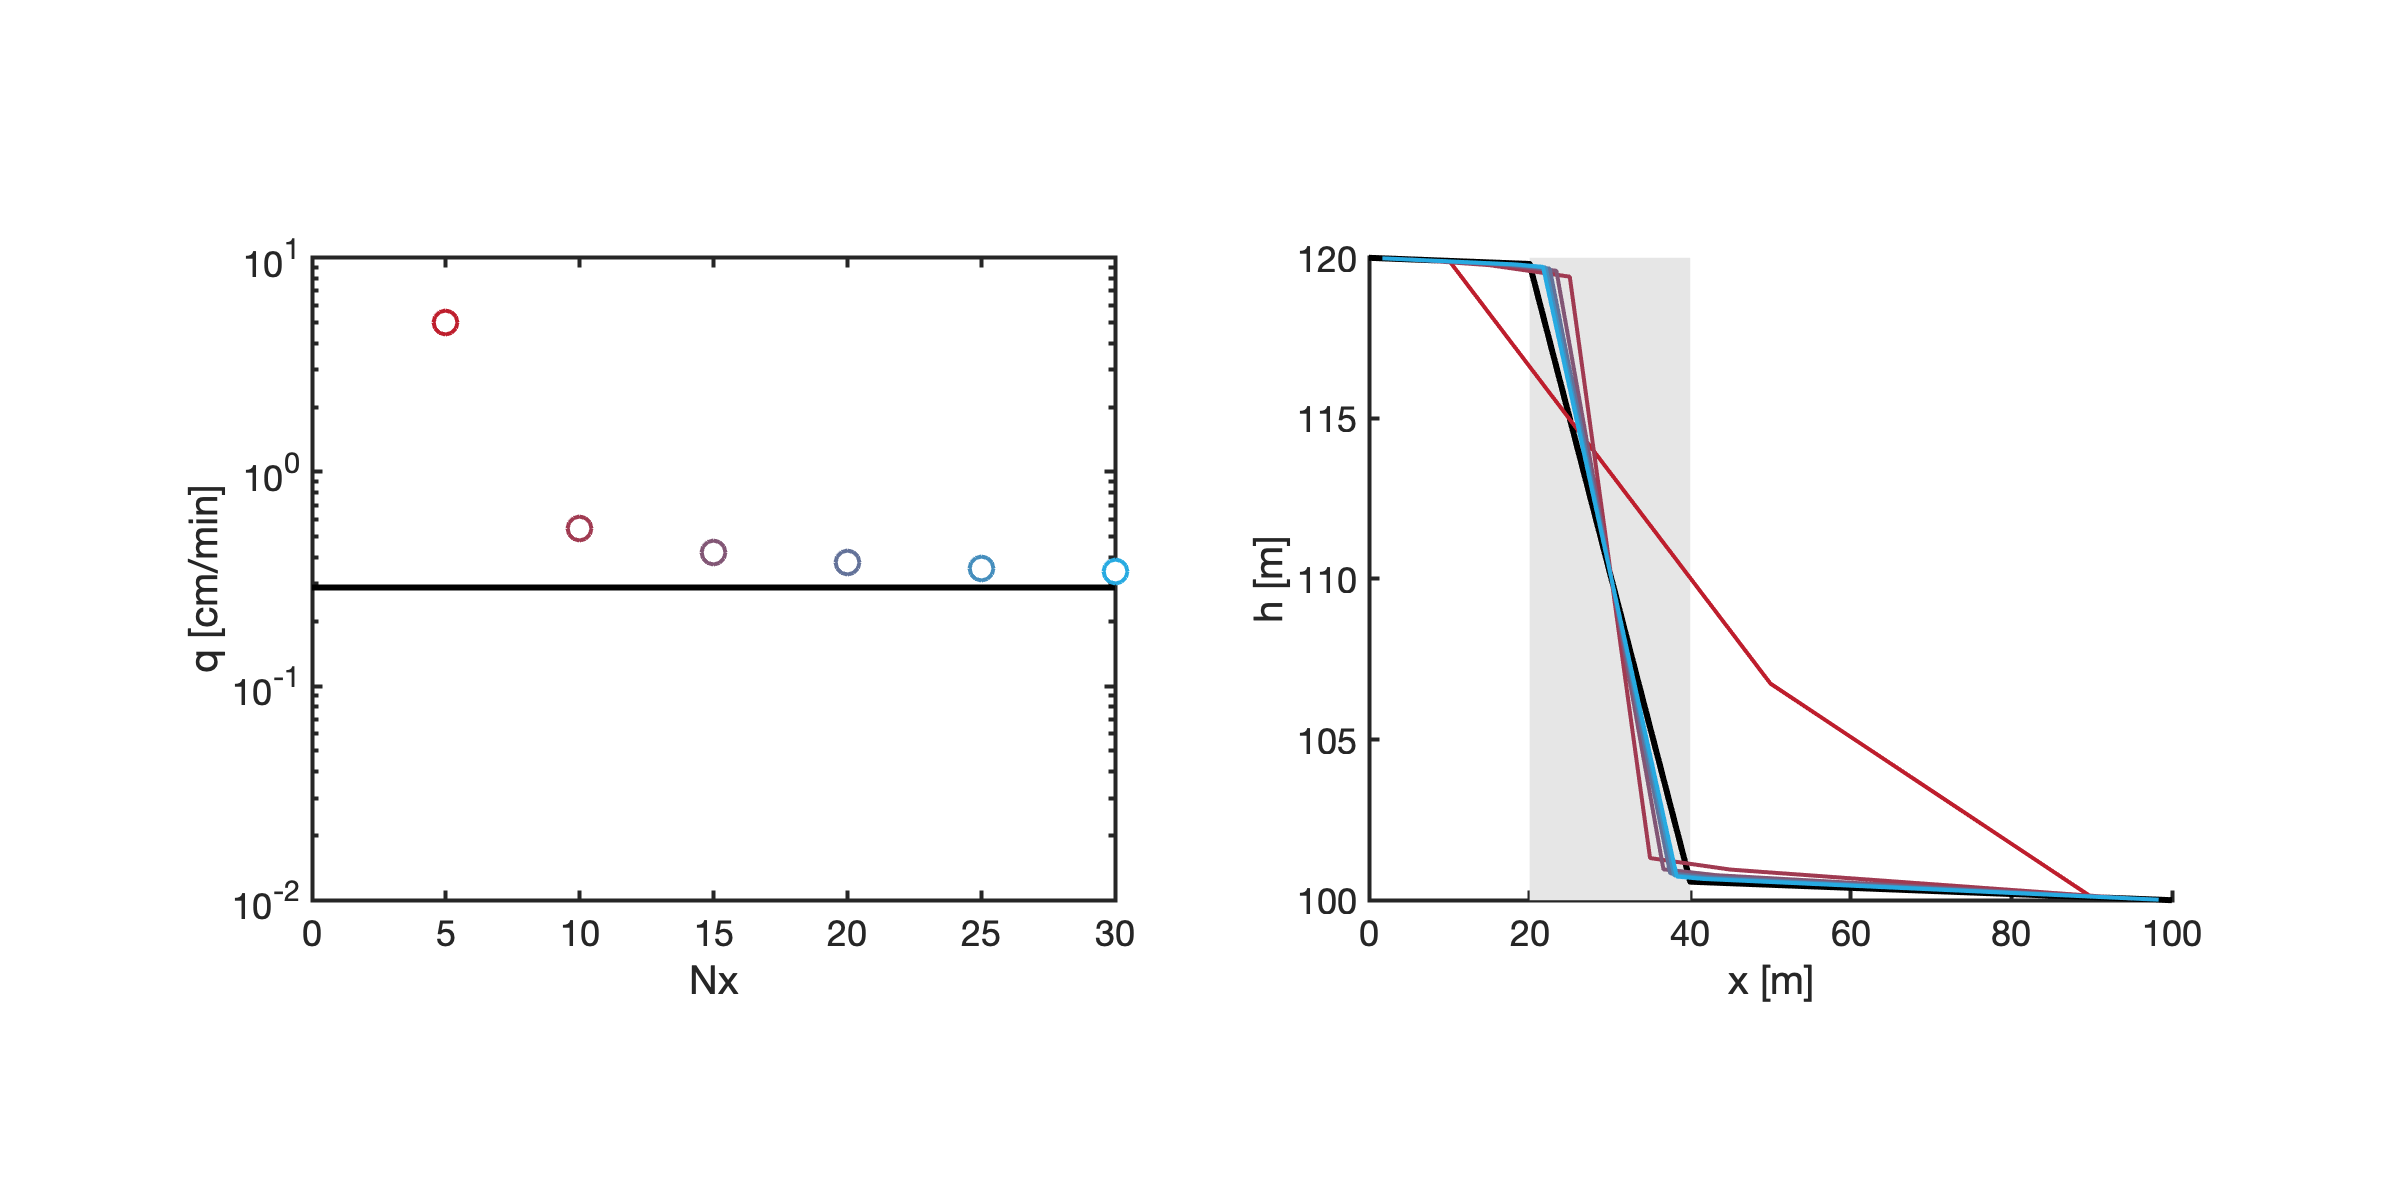

figure('position',[10 10 1200 600])
subplot 121
semilogy([0 Nx(end)],qa*[1 1]*6000,'k-','linewidth',3), hold on
xlim([0 Nx(end)]), ylim([1e-2 1e1])
xlabel 'Nx', ylabel 'q [cm/min]'
pbaspect([1 .8 1])

subplot 122
patch([20 40 40 20],[100 100 120 120],.9*[1 1 1],'edgecolor','none'), hold on
plot(xa,ha,'k-','linewidth',3)
xlabel 'x [m]', ylabel 'h [m]'
pbaspect([1 .8 1])

%% Compute numerical solution
i=1;
for n = Nx
    % build grid
    Grid.Nx = n;
    Grid = build_grid(Grid);
    
    % Hydraulic conductivity
    K = ones(Grid.Nx,1);
    K(Grid.xc<xa(4)) = Kvec(3);
    K(Grid.xc<xa(3)) = Kvec(2);
    K(Grid.xc<xa(2)) = Kvec(1);
    
    % Dirichlet BC's
    BC.dof_dir   = [Grid.dof_xmin;Grid.dof_xmax];
    BC.dof_f_dir = [Grid.dof_f_xmin;Grid.dof_f_xmax];
    BC.dof_neu   = [];
    BC.dof_f_neu = [];
    BC.g = interp1(xa,ha,Grid.xc(BC.dof_dir));
    
    %% Discrete differential operators
    [D,G,C,I,M] = build_ops(Grid);
    
    % Heterogeneous coefficient
    Kd = spdiags(M*K,0,Grid.Nf,Grid.Nf);
    
    % Linear operator & r.h.s.
    L = -D*Kd*G; fs = spalloc(Grid.N,1,0);
    
    %% Build boundary operators
    [B,N,fn] = build_bnd(BC,Grid,I);
    
    %% Solve system
    h = solve_lbvp(L,fs+fn,B,BC.g,N);
    
    %% Compute fluxes
    q = comp_flux(D,Kd,G,h,fs,Grid,BC);
    
    subplot 121
    semilogy(n,q(1)*6000,'o','markeredgecolor',COL(i,:),'markerfacecolor','w')
    xlim([0 Nx(end)])
    subplot 122
    plot(Grid.xc,h,'-','color',COL(i,:)), i=i+1;
    xlim([0,xa(end)])
    drawnow
end

### Harmonic Mean

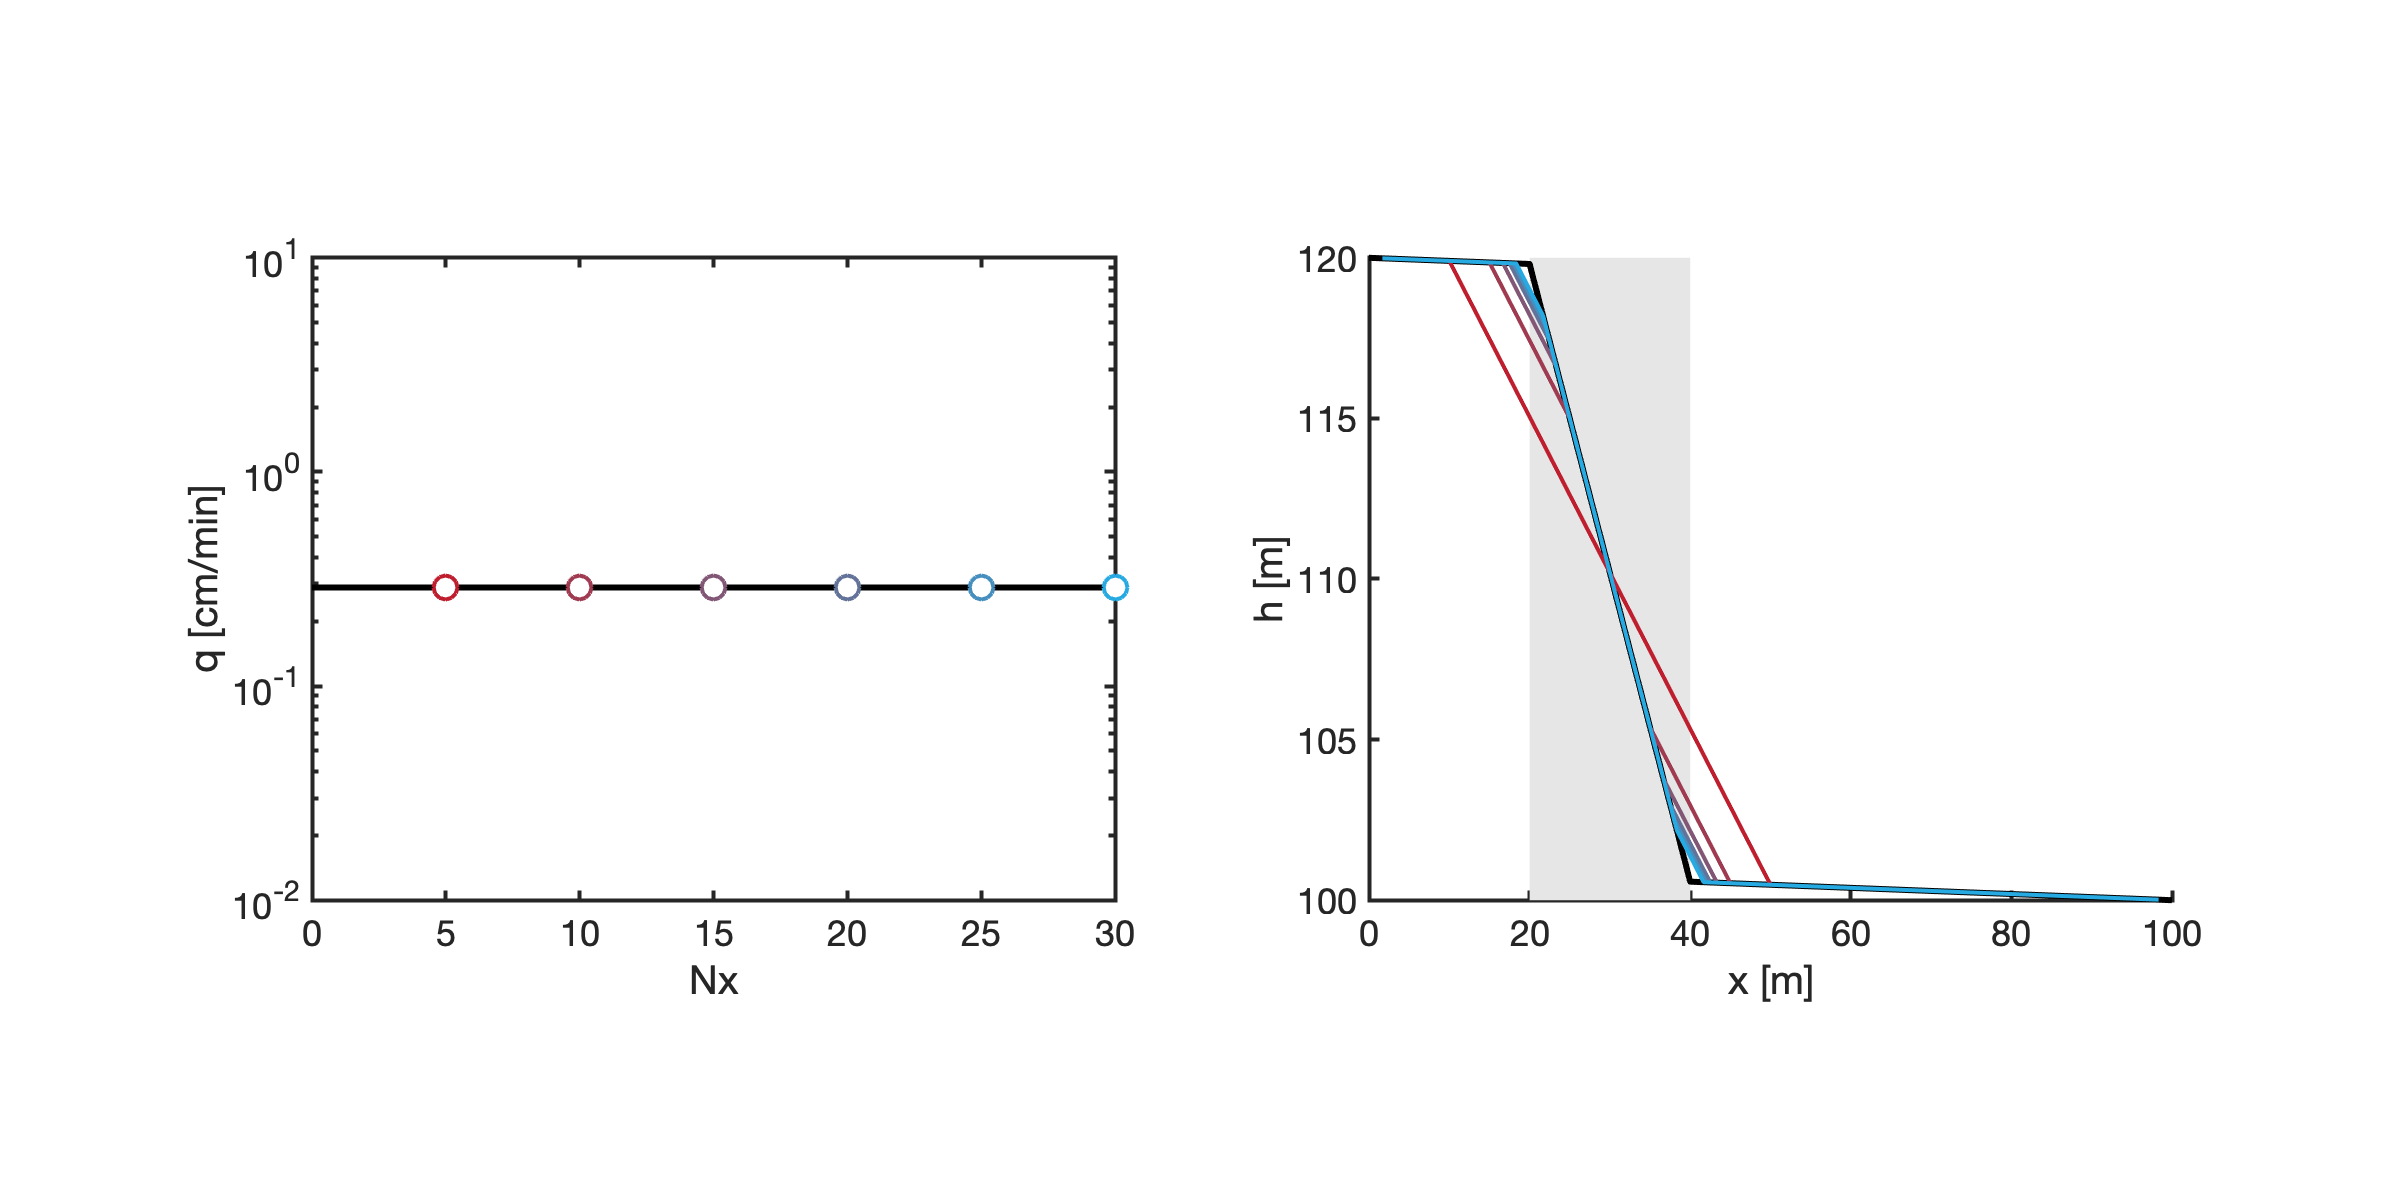

figure('position',[10 10 1200 600])
subplot 121
semilogy([0 Nx(end)],qa*[1 1]*6000,'k-','linewidth',3), hold on
xlim([0 Nx(end)]), ylim([1e-2 1e1])
xlabel 'Nx', ylabel 'q [cm/min]'
pbaspect([1 .8 1])

subplot 122
patch([20 40 40 20],[100 100 120 120],.9*[1 1 1],'edgecolor','none'), hold on
plot(xa,ha,'k-','linewidth',3)
xlabel 'x [m]', ylabel 'h [m]'
pbaspect([1 .8 1])

%% Compute numerical solution
i=1;
for n = Nx
    % build grid
    Grid.Nx = n;
    Grid = build_grid(Grid);
    
    % Hydraulic conductivity
    K = ones(Grid.Nx,1);
    K(Grid.xc<xa(4)) = Kvec(3);
    K(Grid.xc<xa(3)) = Kvec(2);
    K(Grid.xc<xa(2)) = Kvec(1);
    
    % Dirichlet BC's
    BC.dof_dir   = [Grid.dof_xmin;Grid.dof_xmax];
    BC.dof_f_dir = [Grid.dof_f_xmin;Grid.dof_f_xmax];
    BC.dof_neu   = [];
    BC.dof_f_neu = [];
    BC.g = interp1(xa,ha,Grid.xc(BC.dof_dir));
    
    %% Discrete differential operators
    [D,G,C,I,M] = build_ops(Grid);
    
    % Heterogeneous coefficient
    Kd = spdiags(1./(M*(1./K)),0,Grid.Nf,Grid.Nf);
   
    % Linear operator & r.h.s.
    L = -D*Kd*G; fs = spalloc(Grid.N,1,0);
    
    %% Build boundary operators
    [B,N,fn] = build_bnd(BC,Grid,I);
    
    %% Solve system
    h = solve_lbvp(L,fs+fn,B,BC.g,N);
    
    %% Compute fluxes
    q = comp_flux(D,Kd,G,h,fs,Grid,BC);
    
    subplot 121
    semilogy(n,q(1)*6000,'o','markeredgecolor',COL(i,:),'markerfacecolor','w')
    xlim([0 Nx(end)])
    subplot 122
    plot(Grid.xc,h,'-','color',COL(i,:)), i=i+1;
    xlim([0,xa(end)])
    drawnow
end